l_0 = 0.5;
rho = 0.0254;
segment_2m = ArmSegmentFactory.make_2d_2muscle(rho, l_0);
segment_2m.set_mechanics(GinaMuscleMechanics(l_0))

% Base segment load for a bent arm with 5N tip load
external_load = [1; 0; 0];
internal_load = -external_load;

pressures = [0; 40];

opt = optimoptions('fsolve',"MaxFunctionEvaluations", 1e5, "MaxIterations", 4e3);
f_residual = @(g_circ_right) segment_2m.mat_A * segment_2m.get_forces(pressures, g_circ_right) - internal_load;
[g_circ_opt, res] = fsolve(f_residual, [l_0; 0; 0], opt)


Solver stopped prematurely.

fsolve stopped because it exceeded the iteration limit,
options.MaxIterations = 4.000000e+03.



g_circ_opt =     0.4499
         0
    0.0649


res =     0.0016
         0
    0.0867


segment_2m.mat_A * segment_2m.get_forces(pressures, [0.5; 0; 0])

ans =   -10.8669
         0
    0.2760


segment_2m.get_forces(pressures, [0.5; 0; 0])

ans =          0
  -10.8669


%% Attempt to visualize the R^3 -> R^3 function that is the segment equilibrium.

% Sweep the space of reachable internal reaction forces
% The cotangent space is isomorphic to R3 -> Te*g \cong \mathbb{R}^3
% So we can visualize it in R3

pressures = [0; 40];

% Generate a list of input g_circ_right's
% Q: How to parameterize the input space???
N_samples = 100;
v_l = linspace(0.3, 0.7, N_samples);
v_kappa = linspace(-1, 1, N_samples);

cell_g_circ_right = cell(N_samples, N_samples);
cell_actuator_forces = cell(N_samples, N_samples);
cell_internal_forces = cell(N_samples, N_samples);
cell_hsv = cell(N_samples, N_samples);
for i = 1 : length(v_l)
    for j = 1:length(v_kappa)
        g_circ_right_i = [v_l(i); 0; v_kappa(j)];
        cell_g_circ_right{i, j} = g_circ_right_i;
        actuator_forces_i = segment_2m.get_forces(pressures, g_circ_right_i);
        cell_actuator_forces{i, j} = actuator_forces_i;
        cell_internal_forces{i, j} = segment_2m.mat_A * actuator_forces_i;
        cell_hsv{i, j} = [i/length(v_l) * 0.8; j/length(v_kappa) * 0.75 + 0.25; 1];
    end
end

% Reshape the 2d cell array of internal forces into a 3x10^2 matrix so we
% can just plot all of them in order.
mat_g_circ_right = [cell_g_circ_right{:}];
mat_actuator_forces = [cell_actuator_forces{:}];
mat_internal_forces = [cell_internal_forces{:}];
mat_hsv = [cell_hsv{:}];
mat_rgb = hsv2rgb(mat_hsv');

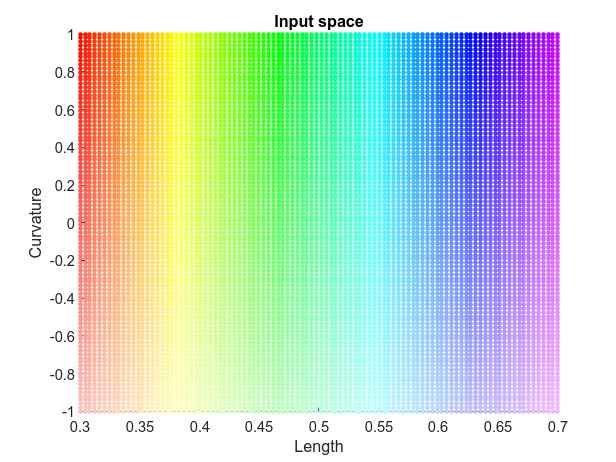

figure()
scatter(mat_g_circ_right(1, :), mat_g_circ_right(3, :), 10, mat_rgb, 'o', 'filled')
title("Input space")
xlabel("Length")
ylabel("Curvature")

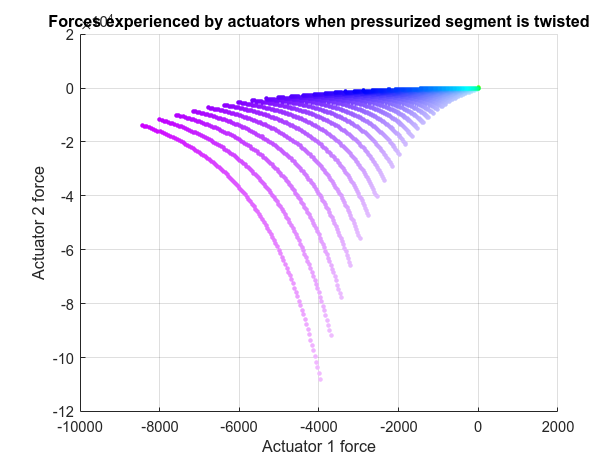

figure()
scatter(mat_actuator_forces(1, :), mat_actuator_forces(2, :), 10, mat_rgb, 'o', 'filled');
grid on
xlabel("Actuator 1 force")
ylabel("Actuator 2 force")
title("Forces experienced by actuators when pressurized segment is twisted")

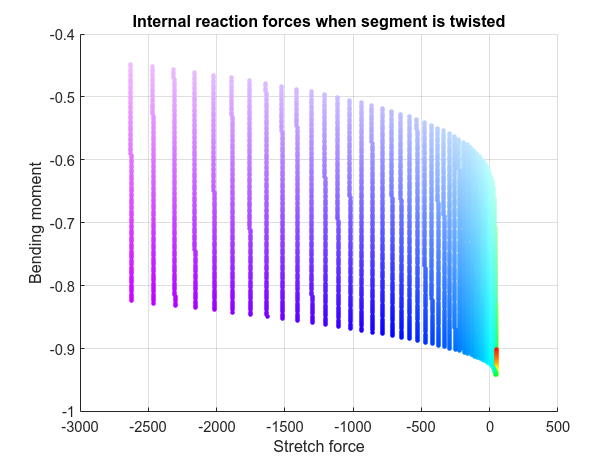

figure()
scatter(mat_internal_forces(1, :), mat_internal_forces(3, :), 10, mat_rgb, 'o', "filled");
grid on
xlabel("Stretch force")
ylabel("Bending moment")
title("Internal reaction forces when segment is twisted")

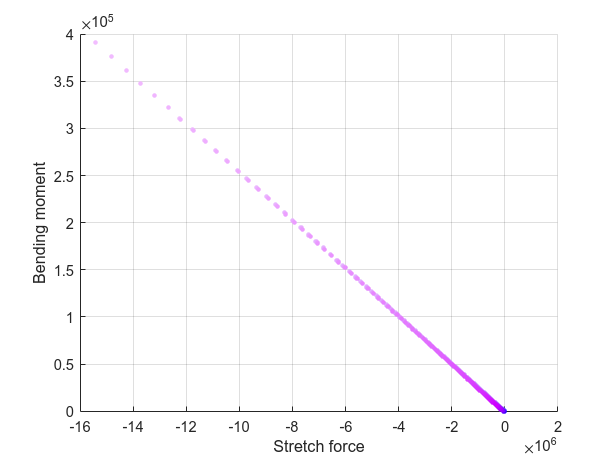

pressures = [0; 40];

% Generate a list of input g_circ_right's
% Q: How to parameterize the input space???
N_samples = 100;
v_l = linspace(0.2, 0.8, N_samples);
v_kappa = linspace(-2, 2, N_samples);

cell_internal_forces = cell(N_samples, N_samples);
cell_hsv = cell(N_samples, N_samples);
for i = 1 : length(v_l)
    for j = 1:length(v_kappa)
        g_circ_right_i = [v_l(i); 0; v_kappa(j)];
        cell_internal_forces{i, j} = segment_2m.mat_A * segment_2m.get_forces(pressures, g_circ_right_i);
        cell_hsv{i, j} = [i/length(v_l) * 0.8; j/length(v_kappa) * 0.75 + 0.25; 1];
    end
end

% Reshape the 2d cell array of internal forces into a 3x10^2 matrix so we
% can just plot all of them in order.
mat_internal_forces = [cell_internal_forces{:}];
mat_hsv = [cell_hsv{:}];
mat_rgb = hsv2rgb(mat_hsv');

figure()
scatter(mat_internal_forces(1, :), mat_internal_forces(3, :), 10, mat_rgb, 'o', "filled");
grid on
xlabel("Stretch force")
ylabel("Bending moment")